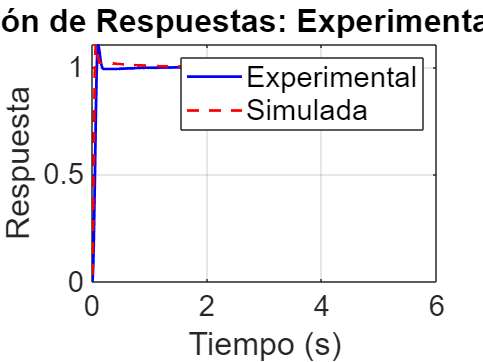

clc; clear; close all;

%% === Definición de la funcion ===
s = tf('s');
K = 2652.28/23;
p = 64.986;
G = K / (s * (s + p));

Kp_opt     = 30.0941;
tau_I_opt  = 0.6387;
tau_D1_opt = 0.0036;
tau_D2_opt = -0.0008;
tau_Dtilde_opt = tau_D1_opt + tau_D2_opt;

%% === Sistema óptimo ===
numerador_PID_opt = K * Kp_opt * tau_D1_opt * (s^2 + s / tau_D1_opt + 1 / (tau_D1_opt * tau_I_opt));
denominador_PID_opt = s^2 * (s + p) + K * Kp_opt * tau_Dtilde_opt * (s^2 + s / tau_Dtilde_opt + 1 / (tau_Dtilde_opt * tau_I_opt));
T_opt = numerador_PID_opt / denominador_PID_opt;

%% === Cargar datos experimentales desde archivo ===
data = load('XXXXXX-MOTOR3POS.txt'); % Asegúrate de que el archivo esté en el mismo directorio
t_exp = data(:,1);        % Tiempo [s]
y_exp = data(:,2);        % Respuesta experimental

%% === Simulación del sistema usando los mismos tiempos que los datos experimentales ===
t_uniform = 0:0.001:max(t_exp);  % Tiempo uniforme a 1 ms
[y_sim_uniform, t_uniform] = step(T_opt, t_uniform);
y_sim = interp1(t_uniform, y_sim_uniform, t_exp, 'linear', 'extrap');  % Interpolación

%% === Graficar comparación entre experimental y simulada ===
figure;
plot(t_exp, y_exp, 'b', 'LineWidth', 1.5); hold on;
plot(t_exp, y_sim, 'r--', 'LineWidth', 1.5);
grid on;

xlabel('Tiempo (s)', 'FontSize', 16);
ylabel('Respuesta', 'FontSize', 16);
title('Comparación de Respuestas: Experimental vs Simulada', 'FontSize', 16);
legend('Experimental', 'Simulada', 'FontSize', 16);
set(gca, 'FontSize', 16); 


info_exp = stepinfo(y_exp, t_exp);  % Experimental
info_sim = stepinfo(T_opt);         % Simulada (modelo)

% Crear tabla comparativa
nombres_metricas = {'RiseTime', 'SettlingTime', 'Overshoot', 'PeakTime', 'Peak'};

valores_exp = [info_exp.RiseTime;
               info_exp.SettlingTime;
               info_exp.Overshoot;
               info_exp.PeakTime;
               info_exp.Peak];

valores_sim = [info_sim.RiseTime;
               info_sim.SettlingTime;
               info_sim.Overshoot;
               info_sim.PeakTime;
               info_sim.Peak];

tabla = table(valores_exp, valores_sim, 'RowNames', nombres_metricas, ...
              'VariableNames', {'Experimental', 'Simulada'});

disp('=== Métricas de Desempeño Comparadas ===');

=== Métricas de Desempeño Comparadas ===


disp(tabla);

                    Experimental    Simulada
                    ____________    ________

    RiseTime          0.051329       0.03105
    SettlingTime       0.14911       0.25713
    Overshoot            10.36        10.935
    PeakTime             0.102      0.065534
    Peak                1.1039        1.1094



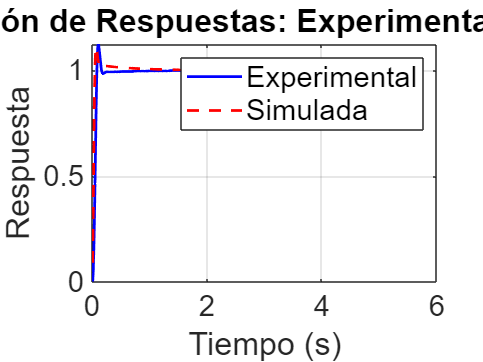

clc; clear; close all;

%% === Definición de la funcion ===
s = tf('s');
K = 2652.28/23;
p = 64.986;
G = K / (s * (s + p));

Kp_opt     = 30.0941;
tau_I_opt  = 0.6387;
tau_D1_opt = 0.0036;
tau_D2_opt = -0.0008;
tau_Dtilde_opt = tau_D1_opt + tau_D2_opt;

%% === Sistema óptimo ===
numerador_PID_opt = K * Kp_opt * tau_D1_opt * (s^2 + s / tau_D1_opt + 1 / (tau_D1_opt * tau_I_opt));
denominador_PID_opt = s^2 * (s + p) + K * Kp_opt * tau_Dtilde_opt * (s^2 + s / tau_Dtilde_opt + 1 / (tau_Dtilde_opt * tau_I_opt));
T_opt = numerador_PID_opt / denominador_PID_opt;

%% === Cargar datos experimentales desde archivo ===
data = load('parte5ms-MOTOR3POS.txt'); % Asegúrate de que el archivo esté en el mismo directorio
t_exp = data(:,1);        % Tiempo [s]
y_exp = data(:,2);        % Respuesta experimental

%% === Simulación del sistema usando los mismos tiempos que los datos experimentales ===
t_uniform = 0:0.001:max(t_exp);  % Tiempo uniforme a 1 ms
[y_sim_uniform, t_uniform] = step(T_opt, t_uniform);
y_sim = interp1(t_uniform, y_sim_uniform, t_exp, 'linear', 'extrap');  % Interpolación

%% === Graficar comparación entre experimental y simulada ===
figure;
plot(t_exp, y_exp, 'b', 'LineWidth', 1.5); hold on;
plot(t_exp, y_sim, 'r--', 'LineWidth', 1.5);
grid on;

xlabel('Tiempo (s)', 'FontSize', 16);
ylabel('Respuesta', 'FontSize', 16);
title('Comparación de Respuestas: Experimental vs Simulada', 'FontSize', 16);
legend('Experimental', 'Simulada', 'FontSize', 16);
set(gca, 'FontSize', 16); 



info_exp = stepinfo(y_exp, t_exp);  % Experimental
info_sim = stepinfo(T_opt);         % Simulada (modelo)

% Crear tabla comparativa
nombres_metricas = {'RiseTime', 'SettlingTime', 'Overshoot', 'PeakTime', 'Peak'};

valores_exp = [info_exp.RiseTime;
               info_exp.SettlingTime;
               info_exp.Overshoot;
               info_exp.PeakTime;
               info_exp.Peak];

valores_sim = [info_sim.RiseTime;
               info_sim.SettlingTime;
               info_sim.Overshoot;
               info_sim.PeakTime;
               info_sim.Peak];

tabla = table(valores_exp, valores_sim, 'RowNames', nombres_metricas, ...
              'VariableNames', {'Experimental', 'Simulada'});

disp('=== Métricas de Desempeño Comparadas ===');

=== Métricas de Desempeño Comparadas ===


disp(tabla);

                    Experimental    Simulada
                    ____________    ________

    RiseTime          0.050659       0.03105
    SettlingTime        0.1492       0.25713
    Overshoot           12.432        10.935
    PeakTime             0.105      0.065534
    Peak                1.1246        1.1094

